% Injector Orifice Sizing
% Updated for Down Bader

clear, clc

mdotOX = 1.096368865; % lbm/s from Vehicle Iteration
Cd = 0.8; % Alright value from textbook range

% mdot = rho*A*V

Dp = 0.2; % Diameter of tangential ports, inches
N = 4; % Number of tangential ports
Apone = pi*(Dp/2)^2 % Area of single tangential port

Apone = 0.0314

Ap = N*Apone % Total area of tangential ports

Ap = 0.1257

rhoOX = 71.38; % lbm/ft3, Lox

Vp = mdotOX*144/(rhoOX*Ap)

Vp = 17.6008


mu = 0.00010550 % lbm/ft*s, From NIST (T=100K, P= 400psia)

mu = 1.0550e-04

Reinlet = rhoOX*Vp*Dp/mu;

% Even with multiple inlets the velocity is constant (from mass cons.)

% From Modern desgin pg 113 "A good starting point for the design level of
% injection flow resistance is about 20% of chamber pressure

Pc = 400; % psi
deltaP = 0.2 * Pc

deltaP = 80

Kl = 1/Cd^2

Kl = 1.5625


% Enter the swirl and apply bernoullis incompressible flow eq.

Vc = sqrt(2*144*32.174*deltaP/(rhoOX*Kl))

Vc = 81.5259


% Mass conservation of swirl to outlet

dpdc_sqr = Vc/Vp

dpdc_sqr = 4.6319

Dc = sqrt(Dp^2*Vp/Vc)

Dc = 0.0929

Ac = pi/4*Dc^2

Ac = 0.0068



% This is the rushed & sloppy section, but it gets the numbers out
% This is the rushed & sloppy section, but it gets the numbers out
% This is the rushed & sloppy section, but it gets the numbers out
% This is the rushed & sloppy section, but it gets the numbers out
% This is the rushed & sloppy section, but it gets the numbers out

% Ac = mdotOX/(Cd*sqrt(2*rhoOX*deltaP)) %Straight tube approximation 
% Switching over to injector swirl sizing forms

Ki = [0.1:.1:4];
C = dpdc_sqr

C = 4.6319

qeq = zeros(40,3);
qeq(:,1) = C*(Ki/Ap);
qeq(:,2) = -Dp*Ki/Ap;
qeq(:,3) = -1;

Dcplot = zeros(40,2);
for i = 1:40
    Dcplot(i,:) = roots(qeq(i,:));
end

Dcplot = Dcplot(:,1)';

Dsplot = Ap./(Ki.*Dcplot)+Dp % Diameter of the swirl chamber

Dsplot =     2.5147    1.8089    1.4965    1.3104    1.1836    1.0900    1.0173    0.9588    0.9104    0.8695    0.8343    0.8036    0.7766    0.7525    0.7309    0.7114    0.6936    0.6774    0.6625    0.6487    0.6359    0.6240    0.6129    0.6025    0.5928    0.5836    0.5750    0.5668    0.5590    0.5517    0.5447    0.5381    0.5317    0.5257    0.5199    0.5143    0.5090    0.5039    0.4991    0.4944


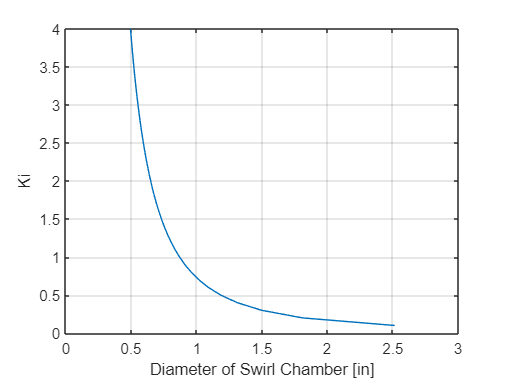

plot(Dsplot,Ki)
xlabel('Diameter of Swirl Chamber [in]')
ylabel('Ki')
grid on

66

ans = 66

% Core Calculations
Reinlet

Reinlet = 2.3817e+06

Dc

Dc = 0.0929

Ki = 1.5

Ki = 1.5000

Ds = Ap/(Ki*Dc)+Dp

Ds = 1.1015

A = (Ds-Dp)*Dc/(N*Dp^2)

A = 0.5236


% Guessing for psi
psi = [0:0.01:1]

psi =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


Aguess = (1-psi).*sqrt(2)./psi.^(3/2)

Aguess = 	1.0e+03 *

       Inf    1.4001    0.4900    0.2640    0.1697    0.1202    0.0905    0.0710    0.0575    0.0477    0.0402    0.0345    0.0299    0.0262    0.0232    0.0207    0.0186    0.0167    0.0152    0.0138    0.0126    0.0116    0.0107    0.0099    0.0091    0.0085    0.0079    0.0074    0.0069    0.0064    0.0060    0.0057    0.0053    0.0050    0.0047    0.0044    0.0042    0.0040    0.0037    0.0035    0.0034    0.0032    0.0030    0.0029    0.0027    0.0026    0.0024    0.0023    0.0022    0.0021


psi = 0.75

psi = 0.7500

Aguess = (1-psi)*sqrt(2)/psi^(3/2)

Aguess = 0.5443


% Spray Angle

beta = atan(2*sqrt(2)*(1-psi)/(sqrt(psi)*(1+sqrt(1-psi))))

beta = 0.4985